clear all; 

# Exercise 3.2 - Inverse Kinematic Algorithm

In this exercise you will setup an inverse kinematics algorithm using the pseudoinverse of the jacobian. 

Consider this UR3e robot: 

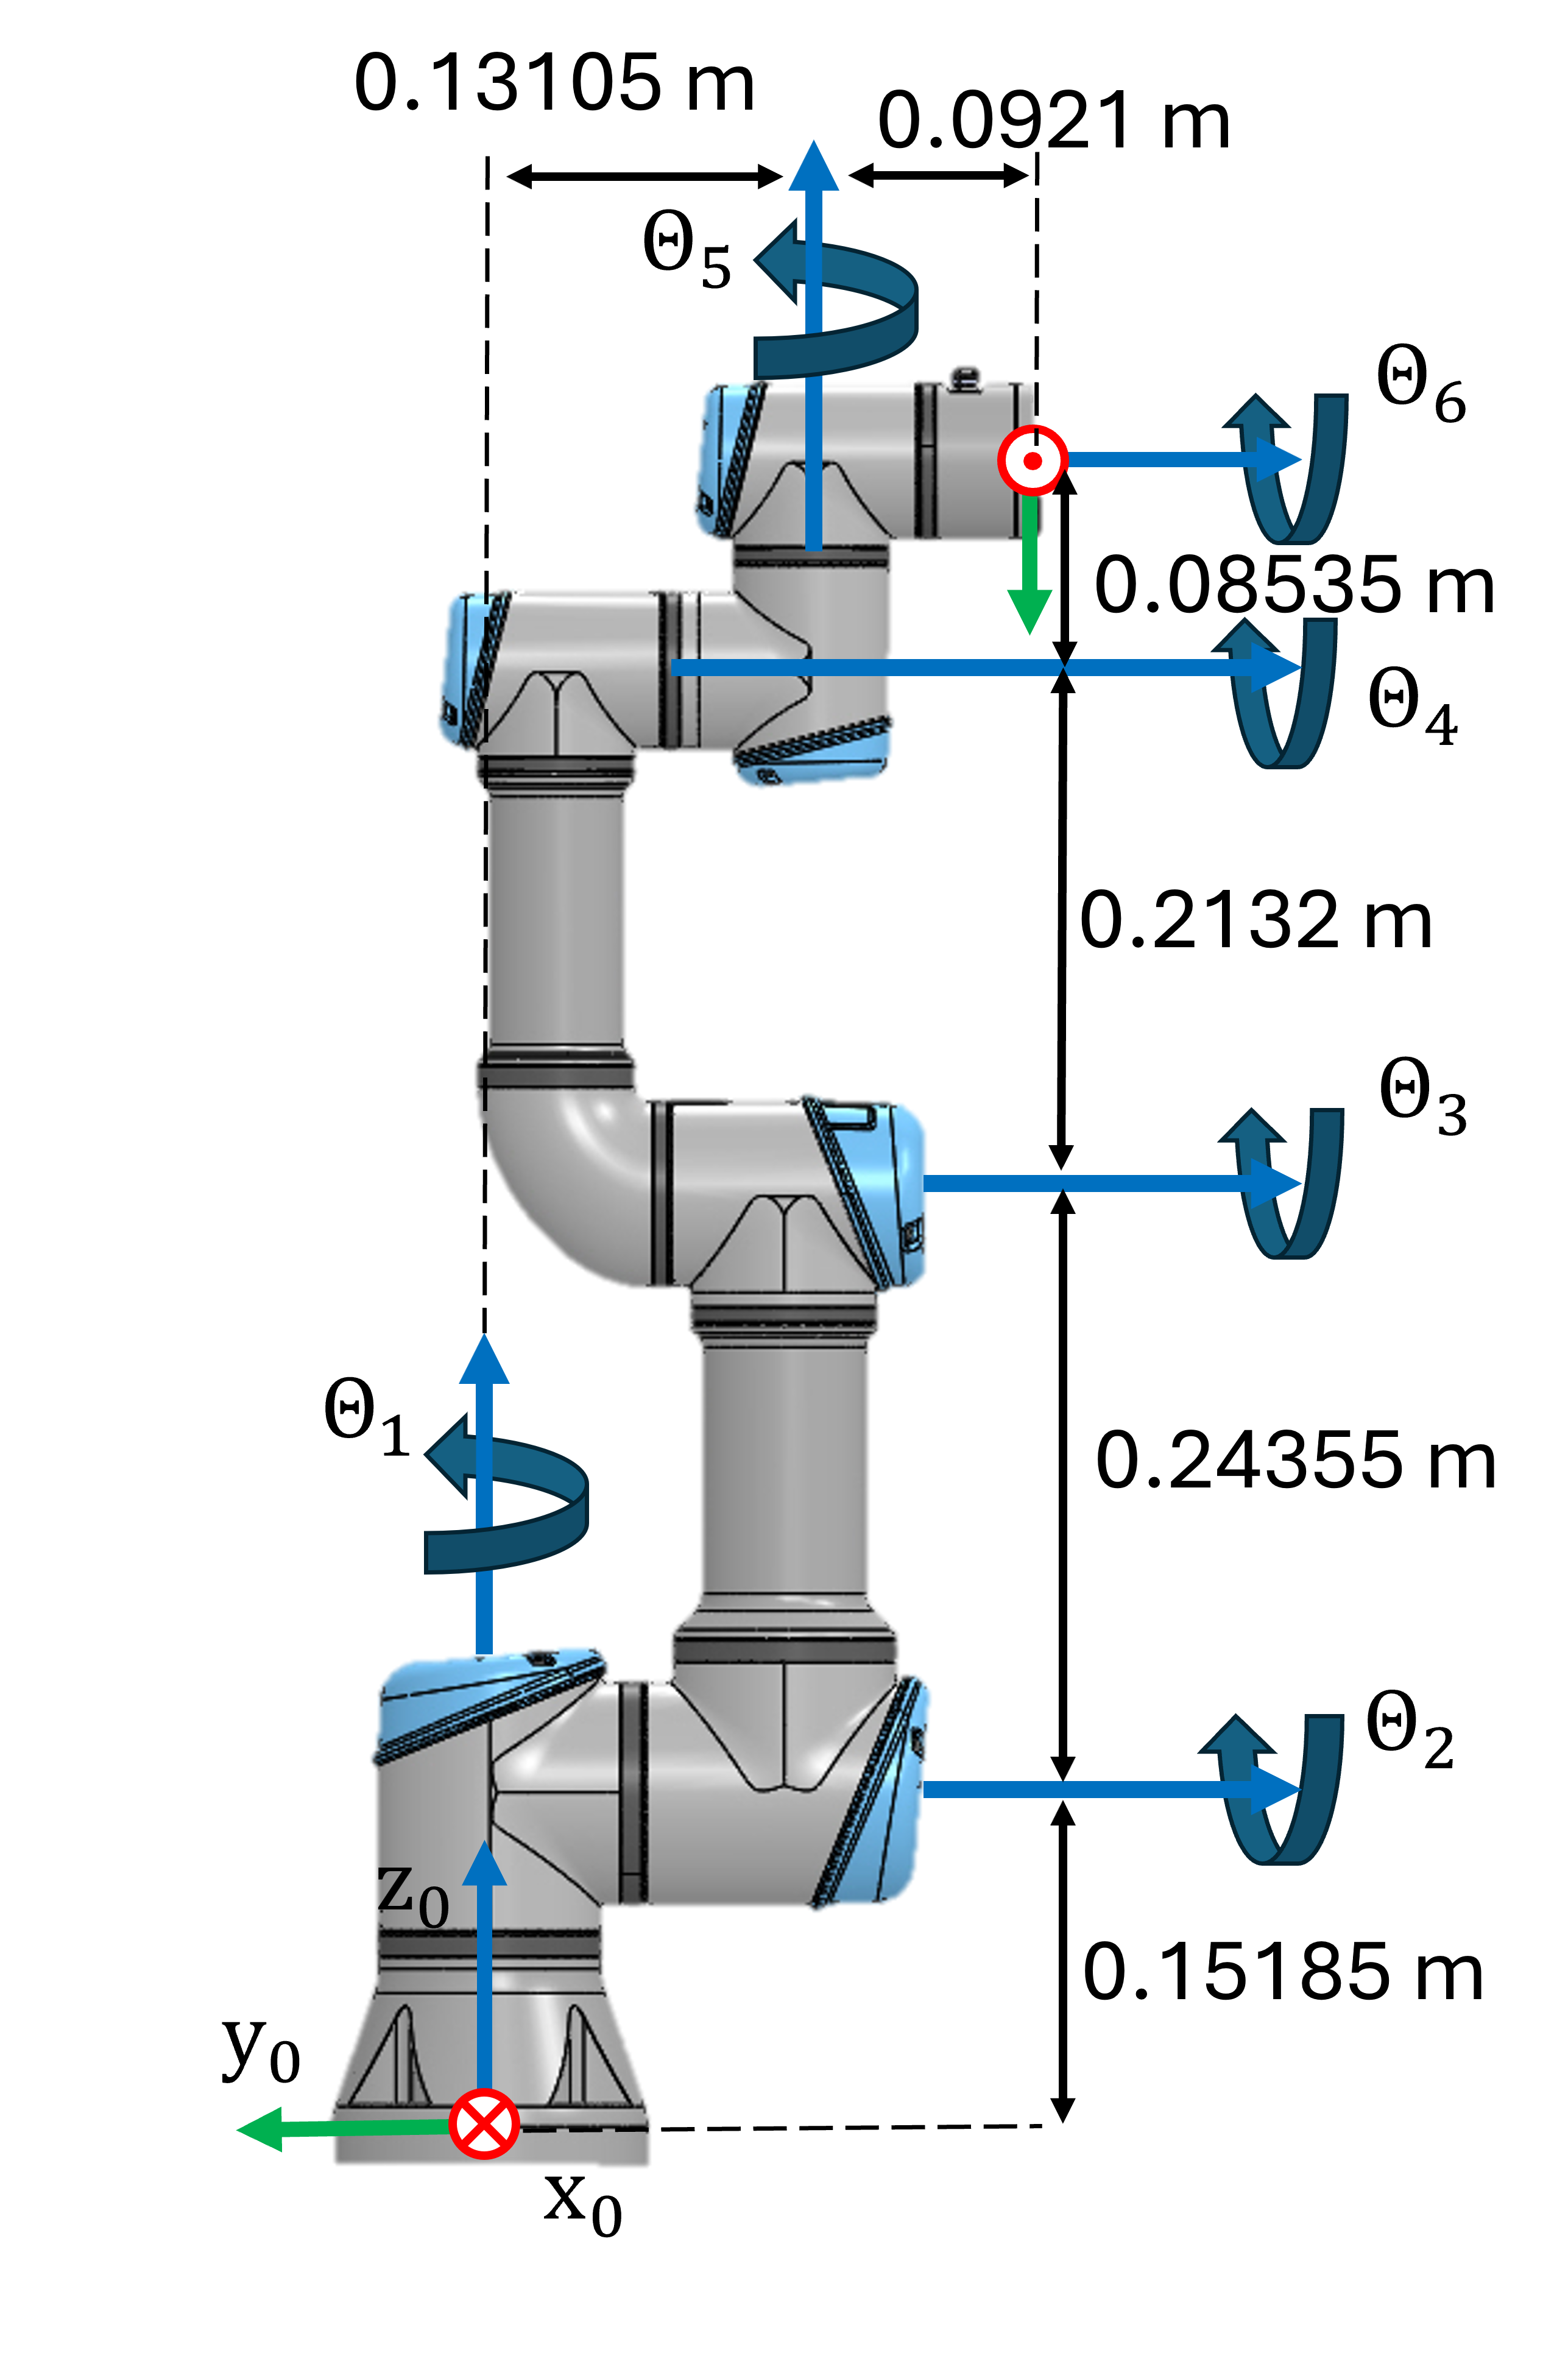

Consider this DH table for the UR3e: 

The control scheme you have to implement is: 

where $k\left(\cdot \right)$ is the forward kinematic of the q. 

## Task 1

Write a function that computes a solution to the inverse kinematic using the pseudoinverse of the Jacobian. The function has the following inputs: 

- the initial joint states as a row vector ($q_0 \in {\mathbb{R}}^{6\textrm{x1}}$)

- desired pose vector using euler angles (ZYZ) $x_{\textrm{desired}} =\left\lbrack \begin{array}{c}
x\\
y\\
z\\
\phi \\
\theta \\
\psi 
\end{array}\right\rbrack$

- gain (k) 

- tolerance (tol)

- max iterations (Imax)

The function should return the required joint states as a row vector ($q\in {\mathbb{R}}^{6\textrm{x1}}$)

For this task, consider $\dot{x_d } =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$ and $\Delta t=0\ldotp 01\;s$

Use the following function name for your solution:

-  PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

You may use the function below to compute the symbolic transform from the base to the endeffector. 

- dh2tf()

Solve this exercise without using the function: 

- inverseKinematics()

% function [q , x] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)
% 
% 
% xdot_desired = [0;0;0;0;0;0];
% dt = 0.01; 
% 
% syms q1 q2 q3 q4 q5 q6 real
% 
% q_syms = [q1,q2,q3,q4,q5,q6];
% 
% DH=[
%     %a       alpha       d       theta
%     0        pi/2        0.15185  q1;
%     -0.24355 0           0       q2;
%     -0.2132  0           0       q3;
%     0        pi/2        0.13105 q4;
%     0        -pi/2       0.08535 q5;
%     0        0           0.0921  q6;
%     ];
% 
% A06=dh2tf(DH);
% 
% p_ee = A06(1:3,4);
% 
% R_ee = A06(1:3,1:3);
% 
% phi = atan2(R_ee(2,3), R_ee(1,3));
% theta = atan2(sqrt(R_ee(1,3)^2+R_ee(2,3)^2),R_ee(3,3));
% psi = atan2(R_ee(3,2), -R_ee(3,1));
% 
% Jphi = [phi; theta; psi];
% 
% 
% Jp = [];
% J_phi_i = [];
% 
% for i=1:6
%     Jp = [Jp, diff(p_ee, q_syms(i))];
%     J_phi_i = [J_phi_i, diff(Jphi, q_syms(i))];
% end
% 
% Ja_sym = simplify([J_phi_i; Jp]); 
% 
% x_sym = [p_ee; Jphi]; 
% q = q0; 
% 
% i=0;
% 
% while i<Imax
% 
%     Ja = double(subs(Ja_sym, q_syms, q'));
%     J_inv = pinv(Ja); % pseudoinverse
% 
%     x = double(subs(x_sym, q_syms, q'));
%     e = x_desired - x;
% 
%     if mod(i, 100)==0
%         x ;
%     end
% 
%     if norm(e) < tol
%         break;          % stop if it converges
%     end
% 
%     ekd = e * k + xdot_desired;     % proportional controller
% 
%     q_dot = J_inv * ekd; 
%     q = q + q_dot * dt; 
%     q = mod(q + pi, 2*pi) - pi;
% 
%     i = i + 1;
% end
% 
% end


You can check your work by clicking the Run: 

% Initialize the time tracking and iteration counting
start_time = tic; 
total_iterations = 0;

q0 = [pi/3,-pi/6, pi/3.5,pi/3,-pi/6, pi/3.5]'; 
%x_desired = [0.3, 0.3, 0.3, 0, 0, 0]'; 
x_desired = [0.1, 0.1, 0.1, 0, 0, 0]';
k = 1; 
tol = 1e-3;
Imax = 1000; 
% Call the PseudoInverseAlgorithm to compute joint angles
[q, x_out] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

q =     1.5257
    1.1142
   -1.5849
   -1.0998
   -1.5708
    1.7763


x_out =     0.1257
   -0.3601
   -0.0306
    1.1320
    3.1368
    2.9518


total_time = toc(start_time)

total_time = 199.9257

solution_error = x_desired - x_out

solution_error =    -0.0257
    0.4601
    0.1306
   -1.1320
   -3.1368
   -2.9518





% Input values
% ================================
% Robot using DH parameters
% ================================
robot = rigidBodyTree('DataFormat','row','MaxNumBodies',6);


DH = [
    0        pi/2      0.15185    0;
   -0.24355  0         0         0;
   -0.2132   0         0         0;
    0        pi/2      0.13105   0;
    0       -pi/2      0.08535   0;
    0        0         0.0921    0];


for i = 1:6
    body = rigidBody("link"+i);
    jnt  = rigidBodyJoint("joint"+i,"revolute");

    % THIS is the correct DH usage for the UR3e table
    setFixedTransform(jnt, DH(i,:), "mdh");

    body.Joint = jnt;

    if i==1
        addBody(robot,body,'base');
    else
        addBody(robot,body,"link"+(i-1));
    end
end

x_desired = [0.1 0.1 0.1 0 0 0];
q0 = [pi/3,-pi/6, pi/3.5,pi/3,-pi/6, pi/3.5];

pos = x_desired(1:3);
eul = x_desired(4:6);

T = trvec2tform(pos) * eul2tform(eul,"ZYX");


ik = inverseKinematics('RigidBodyTree',robot);

weights = [1 1 1 1 1 1];
initialGuess = q0;

[q_inverseIK,solInfo] = ik("link6", T, weights, initialGuess)

q_inverseIK =     0.1563    2.7996   -1.3850   -1.6141   -1.6684    0.0976


solInfo = struct with fields:
           Iterations: 1500
    NumRandomRestarts: 57
        PoseErrorNorm: 0.2480
             ExitFlag: 2
               Status: 'best available'






joint_error = q_PI' - q_IK              % joint differences

joint_error =     3.7936   -0.1118   -0.2981   -3.9238   -0.7151   -0.6006


p_PI = double(subs(A06(1:3,4), q_syms, q_PI(:)'));  
p_IK = tform2trvec(getTransform(robot, q_IK, 'link6'))';  
ee_error = norm(p_PI - p_IK)

ee_error = 0.5749

function [q , x] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

xdot_desired = [0;0;0];
dt = 0.01;

syms q1 q2 q3 q4 q5 q6 real
q_syms = [q1,q2,q3,q4,q5,q6];

q =     1.9328
   -0.3139
    2.7605
   -1.6214
   -1.5990
    0.8976


x_out =     0.0998
    0.0990
    0.1003


solution_error = 1.0e-03 *

    0.1569    0.1569    0.1569
    0.9527    0.9527    0.9527
   -0.2584   -0.2584   -0.2584


DH=[ ...
    0        pi/2        0.15185  q1;
    -0.24355 0           0       q2;
    -0.2132  0           0       q3;
    0        pi/2        0.13105 q4;
    0        -pi/2       0.08535 q5;
    0        0           0.0921  q6];

A06=dh2tf(DH);

p_ee = A06(1:3,4);

Jp = [];

for i=1:6
    Jp = [Jp, diff(p_ee, q_syms(i))];
end

% XYZ Jacobian
Ja_sym = simplify(Jp);      

% XYZ only
x_sym = p_ee;               

q = q0;
i=0;

while i<Imax
    
    Ja = double(subs(Ja_sym, q_syms, q'));
    J_inv = pinv(Ja);
    
    x = double(subs(x_sym, q_syms, q'));

Error using trvec2tform
Expected t to be an array with number of columns equal to 2.

Error in robotics.internal.validation.validateNumericMatrix (line 21)
    validateattributes(M, {'single','double'}, {'nonempty','real','2d',varargin{:}}, ...
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 

    e = x_desired - x;      

    if norm(e) < tol
        break;
    end
    
    ekd = e*k + xdot_desired;
    
    q_dot = J_inv * ekd;
    
    q = q + q_dot*dt;
    q = mod(q + pi, 2*pi) - pi;
    
    i = i + 1;
end

end


q0 = [pi/3,-pi/6, pi/3.5,pi/3,-pi/6, pi/3.5]';
x_desired = [0.1; 0.1; 0.1];  
k = 1;
tol = 1e-3;
Imax = 1000;

[q, x_out] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)
solution_error = x_desired' - x_out



% Using inverse kinematics
robot = rigidBodyTree('DataFormat','row','MaxNumBodies',6);

DH = [
    0        pi/2      0.15185    0;
   -0.24355  0         0         0;
   -0.2132   0         0         0;
    0        pi/2      0.13105   0;
    0       -pi/2      0.08535   0;
    0        0         0.0921    0];

for i = 1:6
    body = rigidBody("link"+i);
    jnt  = rigidBodyJoint("joint"+i,"revolute");

    setFixedTransform(jnt, DH(i,:), "mdh");
    body.Joint = jnt;

    if i==1
        addBody(robot,body,'base');
    else
        addBody(robot,body,"link"+(i-1));
    end
end


q0 = [pi/3,-pi/6, pi/3.5,pi/3,-pi/6, pi/3.5];

% identity rotation
T = trvec2tform(x_desired);

ik = inverseKinematics('RigidBodyTree',robot);

weights = [1 1 1 0 0 0];   

initialGuess = q0;

[q_posOnly,solInfo] = ik("link6", T, weights, initialGuess)

p_IK = tform2trvec(getTransform(robot, q_posOnly, 'link6'))

pos_error = norm(p_IK - x_desired)

%COmparison 
final_error=x_out-p_IK


 
check_exercise('3-2-1')

## Task 2

Extend your function from before. 

Add the input: 

- dt (time for discrete algorithm step)

Add the outputs: 

- total_time (time it takes for the algorithm to find a solution)

- total_iterations (iterations until the solution was found)

- solution_error (the pose square error for the solution configuration$\left({\textrm{error}}_{\textrm{solution}} \left(q\right)={e\left(q\right)}^T \cdot e\left(q\right)\right)$)

Use "tic" and "toc" to measure the computational time. 

Use the following function name for your solution:

-  ExtendedPseudoInverseAlgorithm(t_desired, k, dt, tol, Imax)

Solve this exercise without using the function: 

- inverseKinematics()

function [q,total_time,total_iterations,solution_error] = ExtendedPseudoInverseAlgorithm(t_desired, k, dt, tol, Imax)

tic; 
xdot_desired = [0;0;0;0;0;0];

syms q1 q2 q3 q4 q5 q6 real

q_syms = [q1,q2,q3,q4,q5,q6];

DH=[
    %a       alpha       d       theta
    0        pi/2        0.15185  q1;
    -0.24355 0           0       q2;
    -0.2132  0           0       q3;
    0        pi/2        0.13105 q4;
    0        -pi/2       0.08535 q5;
    0        0           0.0921  q6;
    ];

A06=dh2tf(DH);

p_ee = A06(1:3,4);

R_ee = A06(1:3,1:3);

phi = atan2(R_ee(2,3), R_ee(1,3));
theta = atan2(sqrt(R_ee(1,3)^2+R_ee(2,3)^2),R_ee(3,3));
psi = atan2(R_ee(3,2), -R_ee(3,1));

Jphi = [phi; theta; psi];


Jp = [];
J_phi_i = [];

for i=1:6
    Jp = [Jp, diff(p_ee, q_syms(i))];
    J_phi_i = [J_phi_i, diff(Jphi, q_syms(i))];
end

Ja_sym = simplify([J_phi_i; Jp]); 

x_sym = [p_ee; Jphi]; 
q = q0; 

i=0;

while i<Imax

    Ja = double(subs(Ja_sym, q_syms, q'));
    J_inv = pinv(Ja); 
    
    x = double(subs(x_sym, q_syms, q'));
    e = x_desired - x;
    
    if mod(i, 100)==0
        x 
    end
    
    if norm(e) < tol
        break;
    end
    
    ekd = e * k + xdot_desired; 
    
    q_dot = J_inv * ekd; 
    q = q + q_dot * dt; 
    q = mod(q + pi, 2*pi) - pi;
        i = i + 1;
    end
    
    total_iterations = i;
    total_time = toc; 
    solution_error = e'*e; 

end


Analyze how your algorithm behaves when you change the tolerance, gain or timestep. 